# Using Casadi for Collision Avoidance OCP

Moving obstacle is implemented. The obstacle has a constant speed in [vx,vy,r]. r is yaw rate.

addpath('C:\Program Files\casadi-windows-matlabR2016a-v3.5.5');
import casadi.*

clear sol;
OCP = colliOCP();
OCP.build_basics();
OCP.zero_objective();

Zero objective function applied!


OCP.add_control_bounds(); % use default bounds
OCP.add_initial_conditions(); % use default I.C.'s
OCP.add_path_constraints(); % use default constraints
OCP.add_ego_centers();
Xobs_init = [10,3,0];
% preset 1: 
% vx = -1; vy = 0; r = 0;
% preset 2: 
% vx = -1; vy = 0; r = 0.1;
% preset 3: 
vx = -1; vy = 0; r = 0.3;
[x_traj,y_traj,psi_traj] = OCP.make_const_v_trajectory(Xobs_init,vx,vy,r);
OCP.add_dynamic_obstacle_centers(x_traj,y_traj,psi_traj); % use dynamic obstacle
OCP.add_collision_constraint();
OCP.add_terminal_conditions(); % default T.C.'s
OCP.set_solver_init();
try
    sol = OCP.solve();
    foundSol = true;
catch
    sol = OCP.opti.debug;
    foundSol = false;
end

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:      585
Number of nonzeros in inequality constraint Jacobian.:      608
Number of nonzeros in Lagrangian Hessian.............:      505

Total number of variables............................:      165
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      105
Total number of inequality constraints...............:      293
        inequality constraints with only lower bounds:      190
   inequality constraints with lower and upper bounds:      102
        inequality constraints with only upper bounds:        1

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

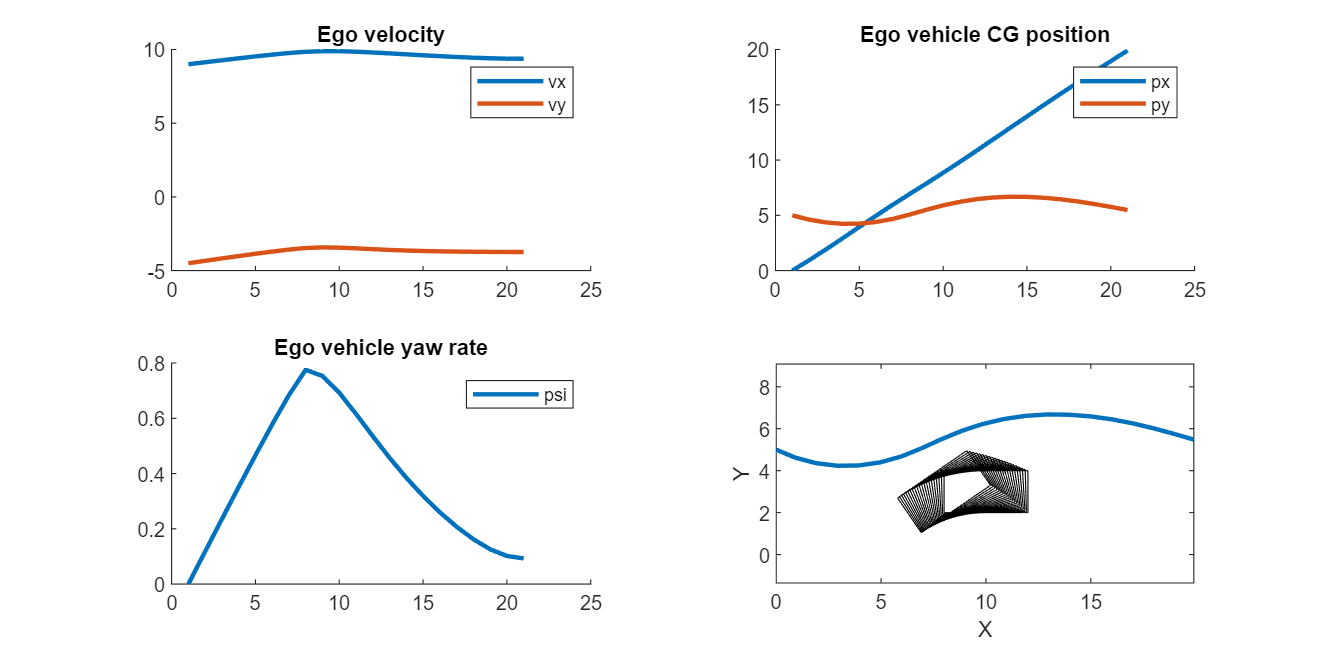

pp.basic_plots(OCP,sol);

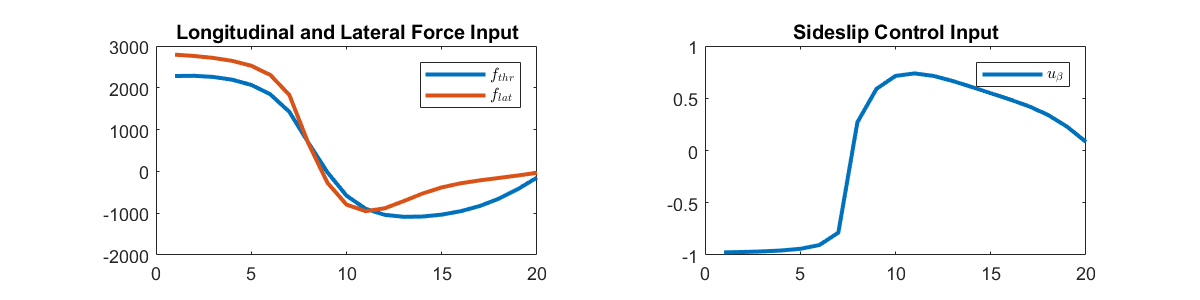

pp.controls_plot(OCP,sol);

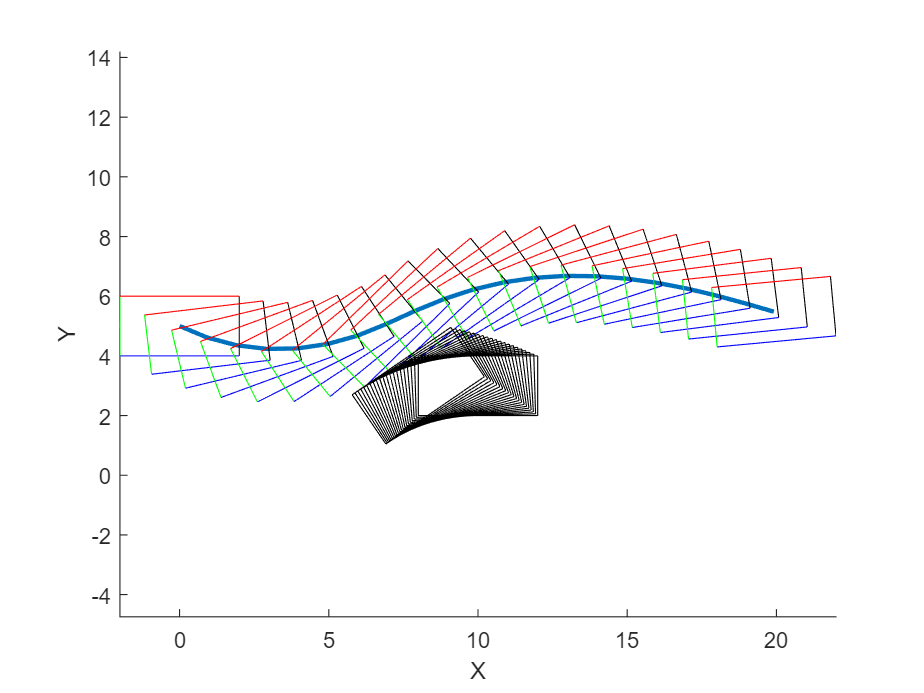

% overlap the vehicle body frame by frame onto the results
pp.rectangle_overlap(OCP,sol);

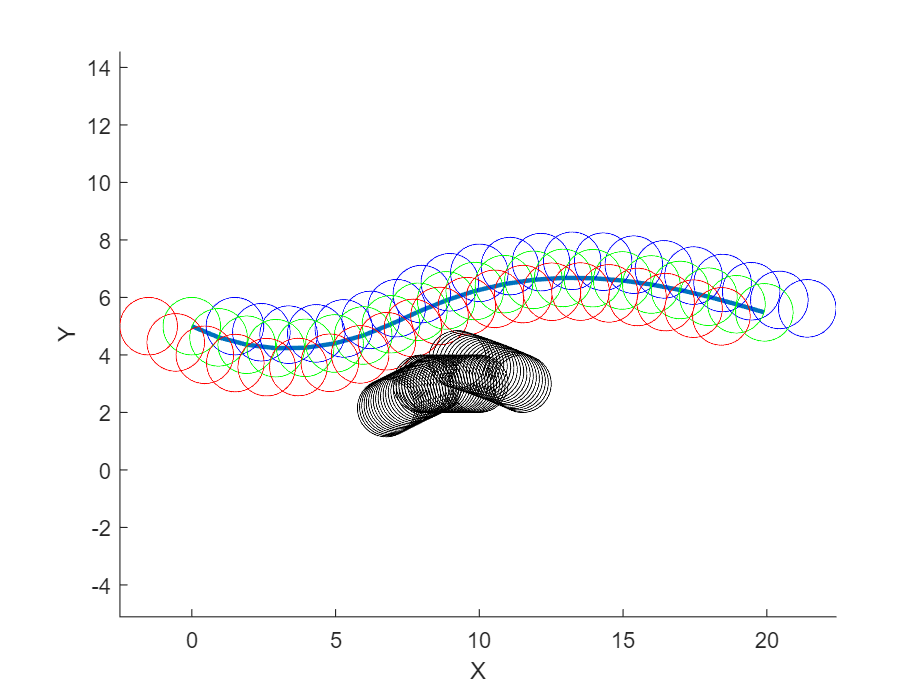

% overlap the vehicle three-circle representation frame-by-frame onto the
% results
pp.circles_overlap(OCP,sol);

Make a video frame by frame, rectangle shape

videoName = 'ex2_preset3';
pp.make_video_rectangles(OCP,sol,videoName,foundSol);

Make a video frame by frame, Ziegler 3-circle shape

videoName = 'ex3_preset3_circ';
pp.make_video_circles(OCP,sol,videoName,foundSol);

Plot the Jacobian and the Hessian:

figure
spy(sol.value(jacobian(OCP.opti.g,OCP.opti.x)))
figure
spy(sol.value(hessian(OCP.opti.f+OCP.opti.lam_g'*OCP.opti.g,OCP.opti.x)))

Helper functions are moved to the post-processing class of `pp`.

PAST SNAPSHOTS

% static obstacle comparison

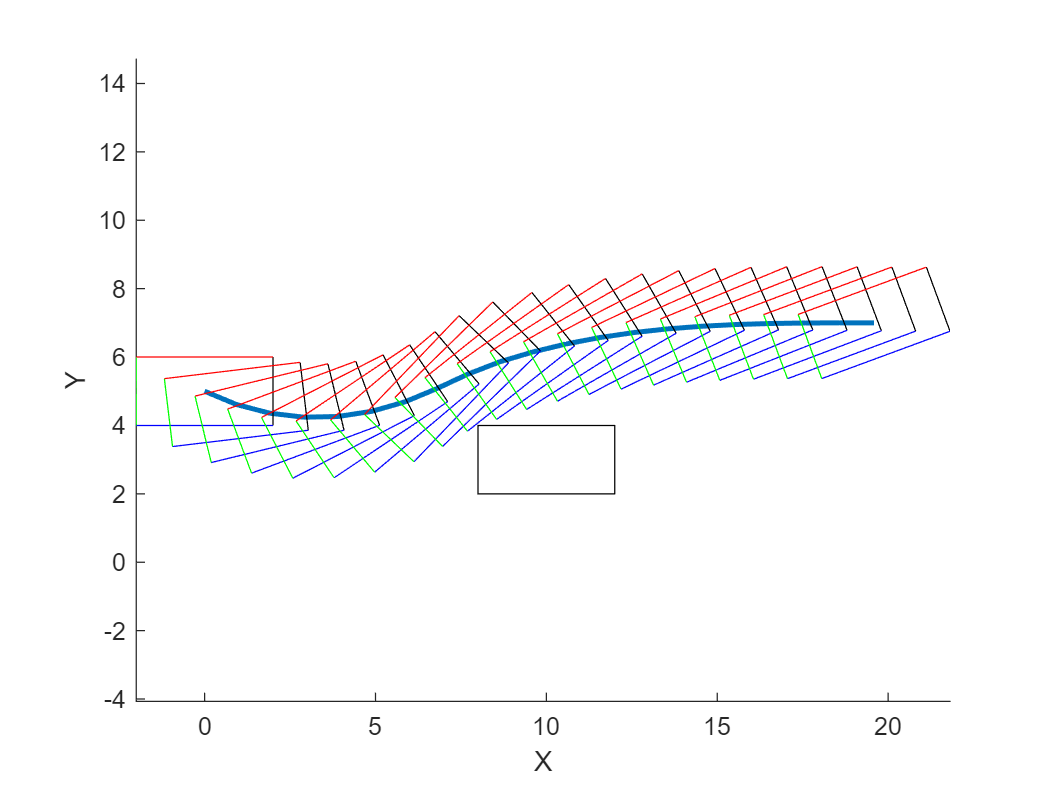

% moving obstacle

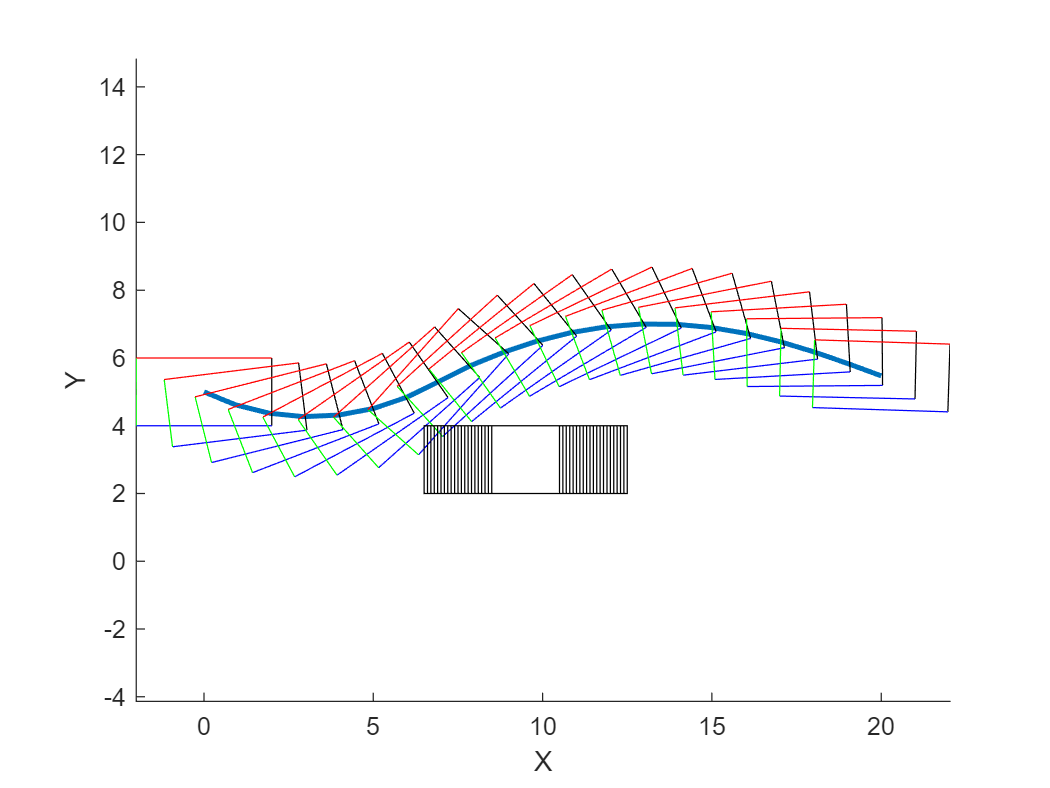

% moving and spinning obstacle (preset 2 vx=-1, vy=0, r=0.1)

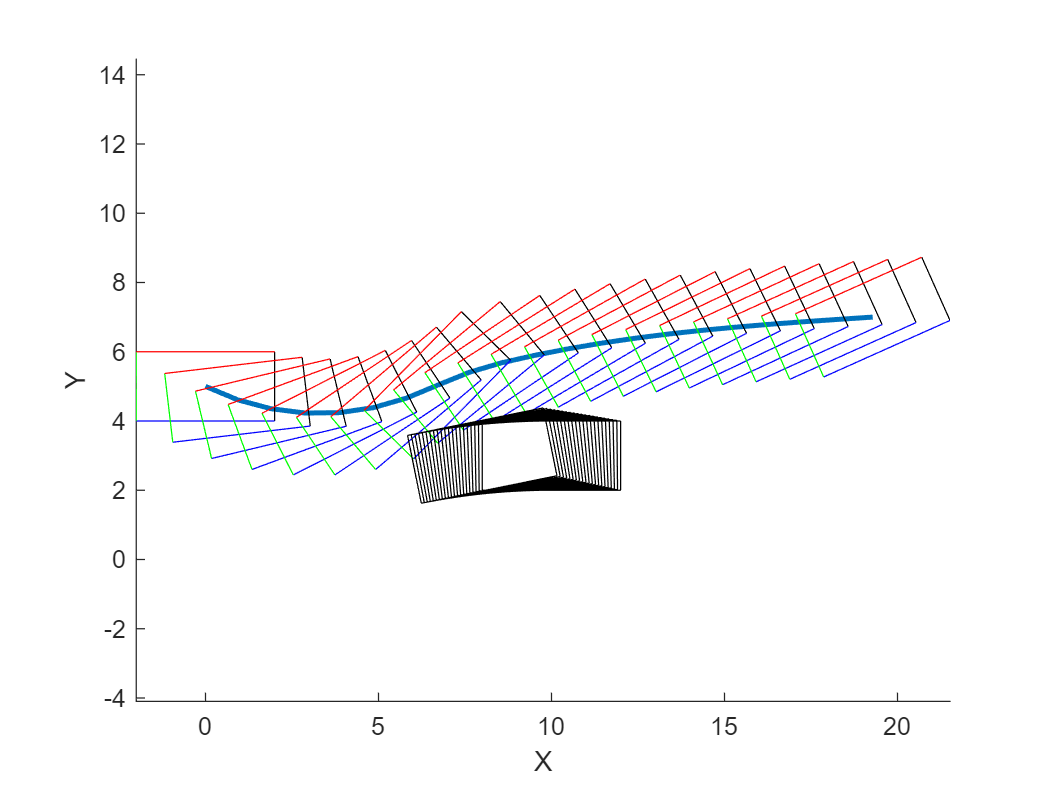

% moving and spinning obstacle (preset 3 vx=-1, vy=0, r=0.3)